clear all
%% 定义函数输入
Start_Point = [0,0,-pi/6];
End_Point = [100,100,-pi/2];
r=15;
% r_s=15;
% r_e=r_s;

sure=3;
R=10+sure;

Stepsize=0.01;
% Avoid_Center = [35,30;
%                 60,50;];
obs=[35,30,10;
     65,60,30;
     -40,-40,10];%[x,y,R]



Draw_map(Start_Point,End_Point,obs,sure);


%% 寻找Dubins路径
[param_all{1},param_best{1}] = Dubins_no_obs(Start_Point, End_Point,r,r,Stepsize);
figure(1)
Draw_path(param_best{1},sure,1,2)
hold off

% figure(2)
% hold on
% for i=1:4
%     subplot(1,4,i);
%     Draw_path(param_all{1}(i),sure)
% end

flag_safe=if_safe(param_best{1}.path,obs,1,2)

flag_safe =      0     0     1


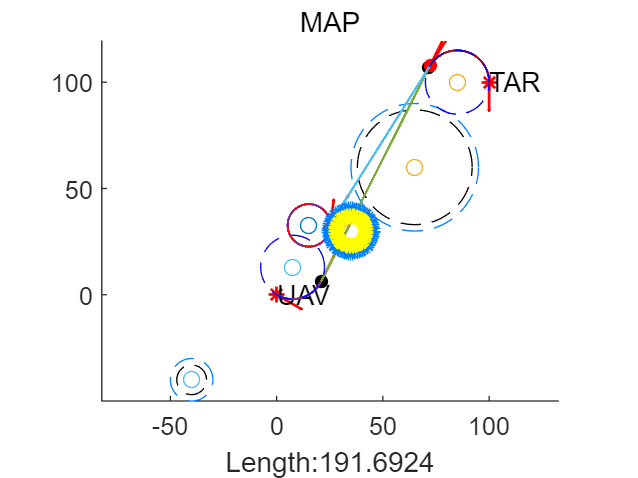


% Start_newPoint=[param_best{1}.point(:,3)',param_best.vtheta(2)];


[param_all{2},param_best{2}] = Dubins_obs(Start_Point,End_Point,obs(1,1:2),r,r,obs(1,3),Stepsize);
figure(2)
% Draw_map(obs,sure);
% Draw_path(param_best{2},sure,1,2)
% hold off

[param_all{3},param_best{3}] = Dubins_obs([param_best{2}.point(:,3)',param_best{2}.vtheta(2)],End_Point,obs(1,1:2),obs(1,3),r,obs(1,3),Stepsize);
figure(2)
% Draw_map(obs,sure);
Draw_path(param_best{3},sure,1,5)
hold off











flag_safe=if_safe(param_best{2}.path,obs)

输入参数的数目不足。

出错 if_safe (第 5 行)
    for j=from_path:to_path


Start_newPoint=[param_best{2}.point(:,3)',param_best{2}.vtheta(2)];

[param_all{3},param_best{3}] = Dubins_obs(Start_newPoint,End_Point,obs(2,1:2),obs(1,3),r,obs(2,3),Stepsize);
figure(3)
Draw_map(obs,sure);
Draw_path(param_best{3},sure)
hold off

[param_all{2,3},param_best{2,3}] = Dubins_obs(Start_newPoint,End_Point,obs(2,1:2),r,r,obs(2,3),Stepsize);
figure(3)
Draw_map(obs,sure);
Draw_path(param_best{2,3},sure)
hold off




flag_safe=if_safe(param_best{2,3}.path,obs)
flag_all=zeros(4,length(obs(:,1)));
for i=1:4
    flag_safe=if_safe(param_all{1,1}(i).path,obs);
    flag_all(i,:)=flag_safe;
end
display(flag_all)


% figure('Name','3')
% for i=1:4
%     for j=1:2
%         DrawD_bset(param_all(j,i),sure)
%     end
% end

% figure(3)
% hold on
% for j=1:2
%     for i=1:4
%         subplot(2,4,i+4*(j-1));
% %         DrawD_bset(param_all(j,i),sure)
%         DrawD_bset(param_all_new(j,i),sure)
%     end
% end

% subplot(2,2,1);
% plot(param_all(2,1).path(1,:),param_all(2,1).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,2);
% plot(param_all(2,2).path(1,:),param_all(2,2).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,3);
% plot(param_all(2,3).path(1,:),param_all(2,3).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,4);
% plot(param_all(2,4).path(1,:),param_all(2,4).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;



